%%%%%%%%%%%%%% JPEG Compression/Decompression Algorithm %%%%%%%%%%%%%%%%
%{
1) convert image to YCbCr color format to separate out illuminance and chrominance spectrums
2) Split the images into 8x8 patches
3) Apply DCT for compression in each of these patches
4) Further suppress the higher frequencies by quantizing the output
5) Use Zig Zag vectorizing to exploit the sparsity of the DCT
6) Use something similar to ZRLE followed by Huffman Encoding to encode the zig zag vector of each patch
7) For simplicity only the illuminance channel is taken into consideration
%}

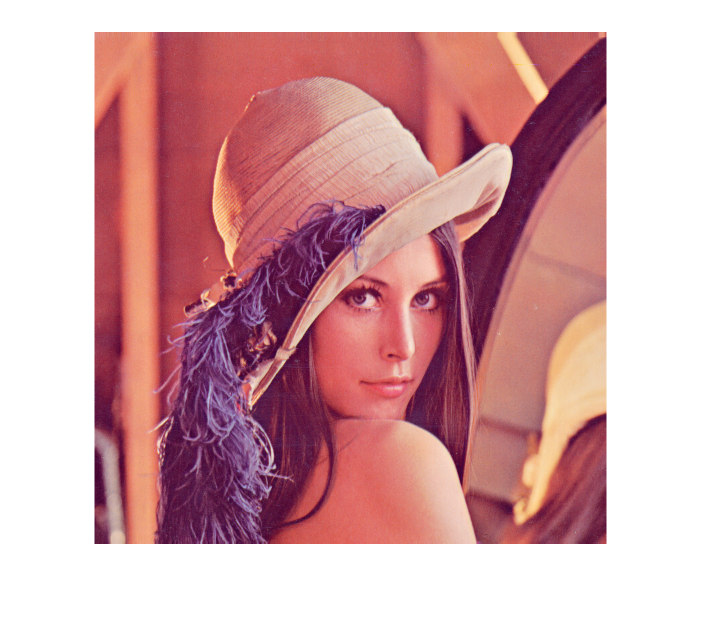

I = imread('lena_png.png');
imshow(I);

w = size(I,1);
h = size(I,2);
c = size(I,3);
init_bits = 8*w*h*c;

**Convert the image to YCbCr format and visualize the illuminance and chrominance components separately**

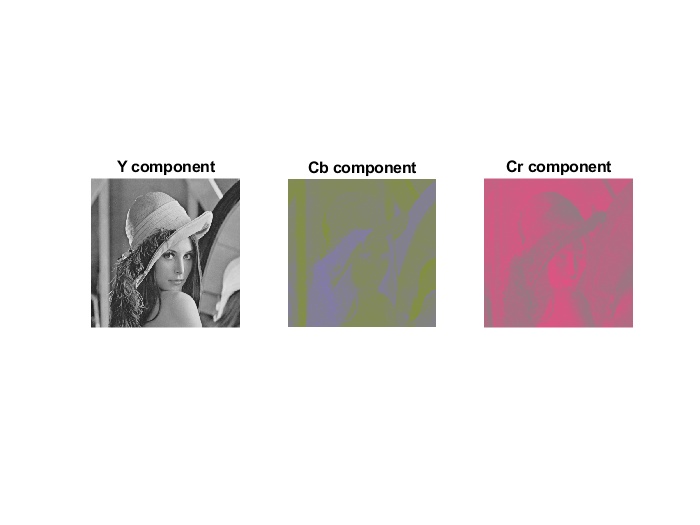

Y = rgb2ycbcr(I);
ch = {'Y', 'Cb', 'Cr'};
figure;
for channel = 1:3
    subplot(1,3,channel)
    Y_plot = Y;
    Y_plot(:,:,setdiff(1:3,channel)) = 128;
    imshow(ycbcr2rgb(Y_plot))
    title([ch{channel} ' component'])
end

**Our human eye is more sensitive to illuminance than colour. To illustrate this, lets downsample**

**chrominance and illuminance components by a factor of 10 separately and plot the results.**

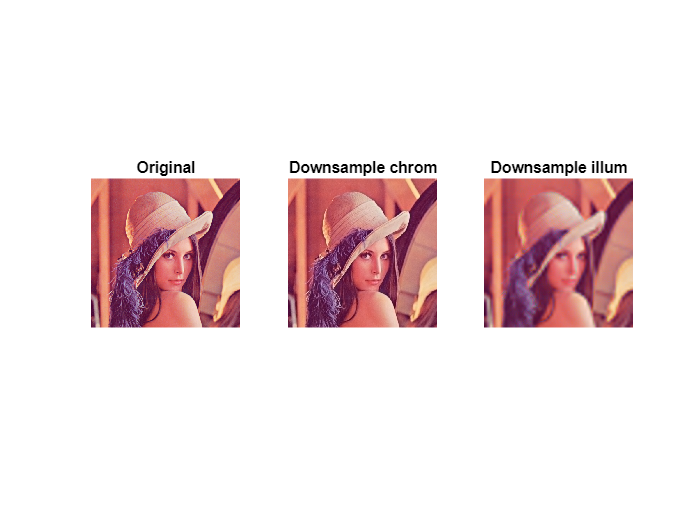

%{
resampling with a reduced sampling rate can be thought of as transmitting
only the contents of a resized image of factor 0.1. In the receiver side,
the original image can be reconstructed by interpolation. This means that although
we lose information by resizing the image, we can interpolate with the
available information at the receiver. Now we are going to compare how much
lost information is tolerable while linear interpolation for illuminance and chrominance channels
respectively.
%}

figure;
subplot(1,3,1)
imshow(I)
title('Original')

subplot(1,3,2)
Y_d = Y;
Y_d(:,:,2) = imresize(imresize(Y_d(:,:,2),[w/10,h/10]), [w,h]);
Y_d(:,:,3) = imresize(imresize(Y_d(:,:,3),[w/10,h/10]), [w,h]);
imshow(ycbcr2rgb(Y_d))
title('Downsample chrom')

subplot(1,3,3)
Y_d = Y;
Y_d(:,:,1) = imresize(imresize(Y_d(:,:,1),[w/10,h/10]), [w,h]);
imshow(ycbcr2rgb(Y_d))
title('Downsample illum')

**As we can see above, transmitting only 512*512*2/100 (for both Cb and Cr) information is sufficient for appealing reconstruction.**

**Whereas, transmitting 512*512/10 information itself leads to very bad reconstruction**

Q = [16 11 10 16 24 40 51 61 ;
     12 12 14 19 26 28 60 55 ;
     14 13 16 24 40 57 69 56 ;
     14 17 22 29 51 87 80 62 ;
     18 22 37 56 68 109 103 77 ;
     24 35 55 64 81 104 113 92 ;
     49 64 78 87 103 121 120 101;
     72 92 95 98 112 100 103 99];

**Since JPEG contains quantization, downsampling and rounding off, its a lossy algorithm. Lets visualize the reconstructed image and see whether**

**it has appreceable reconstruction. **

Y_d = double(Y);
Cb = imresize(Y_d(:,:,2),[w/2,h/2]);        %downsampling by a factor of 2
Cr = imresize(Y_d(:,:,3),[w/2,h/2]);

A = zeros(size(Y_d(:,:,1)));
B = zeros(size(Cb));
C = zeros(size(Cr));

for j = 1:8:w-7
    for k = 1:8:h-7
        block = Y_d(j:j+7,k:k+7,1);
        block = double(block);
        block = block-128;                  %to centre them around 0.
        block = dct2(block);                %dct2
        if j == 1 && k == 1
            fprintf("Before Quantization");
            block
        end
        block = round(block./Q);            %quantization
        if j == 1 && k == 1
            fprintf("After Quantization");
            block
        end
        Y_d(j:j+7,k:k+7,1) = double(block);
        A(j:j+7,k:k+7) = idct2(Q.*block);
        A(j:j+7,k:k+7) = A(j:j+7,k:k+7) + 128;
    end
end

Before Quantization

block =   205.0000    4.4479    3.1447   -0.3117    0.5000   -0.4787   -4.8204    5.7022
    6.1755   -0.3818    0.5771   -4.7311    1.6663    2.9418   -3.4882    3.0411
   -4.1110   -0.5982   -1.3536    1.4391   -0.5412   -0.5622    1.6213   -1.5250
    2.2276    1.3524    1.4208    1.2492   -0.6916   -1.1687    0.2569    0.2462
   -1.5000   -1.3426   -0.2474   -1.6225    1.5000    0.9690   -1.2505    0.0316
    1.7891    0.6753   -1.5507    0.0206   -1.6648    0.7080    1.2072    0.5418
   -2.0855    0.0428    2.6213    1.6321    1.3066   -2.1278   -0.6464   -1.1118
    1.4833   -0.2695   -2.0047   -1.6312   -0.6881    1.8474    0.1841    0.9247


After Quantization

block =     13     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


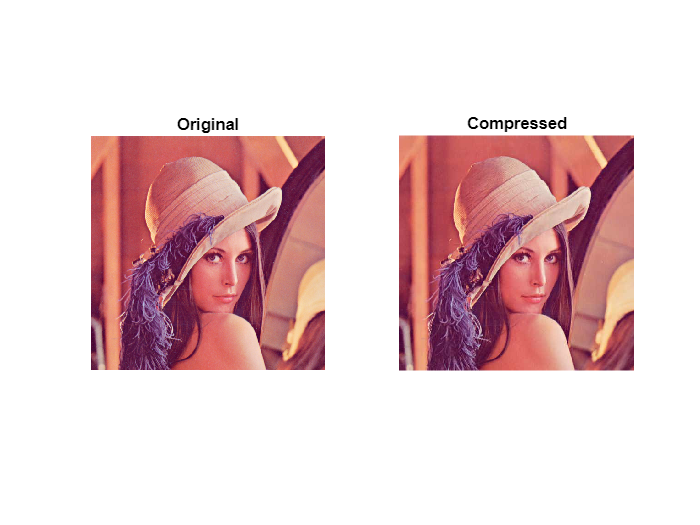

for j = 1:8:w/2-7
    for k = 1:8:h/2-7
        block = Cb(j:j+7,k:k+7);
        block = double(block);
        block = block-128;
        block = dct2(block);
        block = round(block./Q);
        Cb(j:j+7,k:k+7,1) = double(block);
        B(j:j+7,k:k+7) = idct2(Q.*block);
        B(j:j+7,k:k+7) = B(j:j+7,k:k+7) + 128;

        block = Cr(j:j+7,k:k+7);
        block = double(block);
        block = block-128;
        block = dct2(block);
        block = round(block./Q);
        Cr(j:j+7,k:k+7,1) = double(block);
        C(j:j+7,k:k+7) = idct2(Q.*block);
        C(j:j+7,k:k+7) = C(j:j+7,k:k+7) + 128;
    end
end

compressed = zeros(size(Y));
compressed(:,:,1) = A;
compressed(:,:,2) = imresize(B, [w,h]);             %linear interpolation with available downsampled information
compressed(:,:,3) = imresize(C, [w,h]);

figure;
subplot(1,2,1)
imshow(ycbcr2rgb(Y))
title('Original');subplot(1,2,2)
imshow(ycbcr2rgb(uint8(compressed)));
title('Compressed');

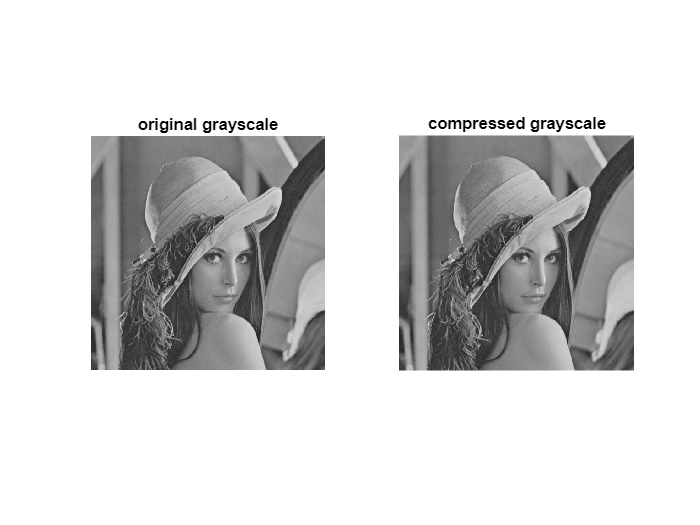

figure;
subplot(1,2,1)
imshow(Y(:,:,1))
title("original grayscale")
subplot(1,2,2)
imshow(uint8(A))
title("compressed grayscale")

fprintf("Number of non zero elements in the original image: %d\n" + ...
    "Number of non zero elements in the compressed image: %d\n" + ...
    "Number of non zero elements in the original illuminance channel: %d\n" + ...
    "Number of non zero elements in the compressed illuminance channel: %d", ...
    nnz(Y), nnz(Y_d(:,:,1))+nnz(Cb)+nnz(Cr), nnz(Y(:,:,1)), nnz(Y_d(:,:,1)));

Number of non zero elements in the original image: 786432
Number of non zero elements in the compressed image: 33044
Number of non zero elements in the original illuminance channel: 262144
Number of non zero elements in the compressed illuminance channel: 25969

**JPEG COMPRESSION**

ZigZags = zigzag(Y_d(:,:,1));               % Zig Zag vectorization
ZigZags(1,:)

ans =     13     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%ZRLE
zrles = ZRLE(ZigZags);
zrles(1:8)

ans =      0    13     1     1   500     0    12     0


[y,dicts,tree] = huff(zrles);               % Obtain the table, tree, encoding for each patch and save them

fid = fopen("code_lenna.txt", "wt");
fprintf(fid, "%s", y);
fclose(fid);

save("table.mat", "dicts");

save("tree.mat", "tree");

**Compression advantage**

comp_size = strlength(y);
init_size = 8*w*h;
efficiency = init_size/comp_size;
fprintf("Original Size: %d\ncompressed size: %d\ncompression factor: %f", init_size, comp_size, efficiency);

Original Size: 2097152
compressed size: 147804
compression factor: 14.188736

** JPEG DECOMPRESSION**

fid = fopen("code_lenna.txt", 'rt');
y = fscanf(fid, '%s');
fclose(fid);

dicts = importdata('table.mat');
tree = importdata("tree.mat");
dicts{1}

ans = 4×3 string array
    "0"      "0.2"    "110"
    "13"     "0.2"    "111"
    "500"    "0.2"    "10" 
    "1"      "0.4"    "0"  


izrles = decode(y,tree);                % decode the received message using huffman tree

iZigZags = decodeZRLE(izrles);          % invert the ZRLE step

**Convert the Zig Zag vector to matrix**

N = 8;                                  % 8th diagonal is the central diagonal
n = 1:2*N-1;
arr = 8 - abs(n-8);                     % Number of (i,j) pairs contained by each diagonal - 1 2 3 ... 8 7 6 .. 1 total 15
iY_d = zeros(size(Y_d(:,:,1)));
for k = 1:size(iZigZags, 1)
    r = iZigZags(k,:);                  % obtain the zig zag vector corresponding to one 8x8 patch
    c = mat2cell(r, 1, arr);            % Split the zig zag vector to various diagonals using mat2cell.
    for i = 1:N
        for j = 1:N
            sum = i+j;
            nth_index = sum-1;          % sum - 1 is the diagonal number under itnerest

            % In a given diagonal, the (i,j) pairs are arranged in the
            % ascending order of i/j depending whether the sum is even or
            % odd

            % If the diagonal index is less then the central diagonal index
            % the elements start with (1,j) or (i,1). But if the
            % diagonal index is greater than the central diagonal, then
            % elements dont start with (1,j) or (i,1). So we subtract
            % (diag_index - central_diag_index) from the starting
            % row/column index which in turn is dependent on the sum being
            % even or odd

            if rem(sum,2) == 0
                if nth_index <= N
                    offset = j;         
                else
                    offset = j - (nth_index-N);     % Now the offset starts from 1
                end
            else
                if nth_index <= N
                    offset = i;
                else
                    offset = i-(nth_index-N);       % Now the offset starts from 1
                end
            end
            ipatch(i,j) = c{nth_index}(offset);     % Access nth diagonal from the cell array and use the computed offset
        end
    end
    
    % Reconstruction of patches to form the entire 512x512 matrix
    row_patch_index = ceil(k/64);
    r_index = N*(row_patch_index-1)+1;
    col_patch_index = rem(k-1,64);
    c_index = N*(col_patch_index)+1;
    
    iY_d(r_index:r_index+7, c_index:c_index+7) = ipatch;
end

% Applying idct2 to the dequantized matrix and adding 128 to make the
% entried from 0 - 255
for i = 1:8:w-7
    for j = 1:8:h-7
        block = iY_d(i:i+7, j:j+7);
        block = double(block);
        iY_d(i:i+7,j:j+7) = idct2(Q.*block);
        iY_d(i:i+7,j:j+7) = iY_d(i:i+7,j:j+7)  + 128;
    end
end

**Notice that the decompressed image is visually identical to that of the original image. **

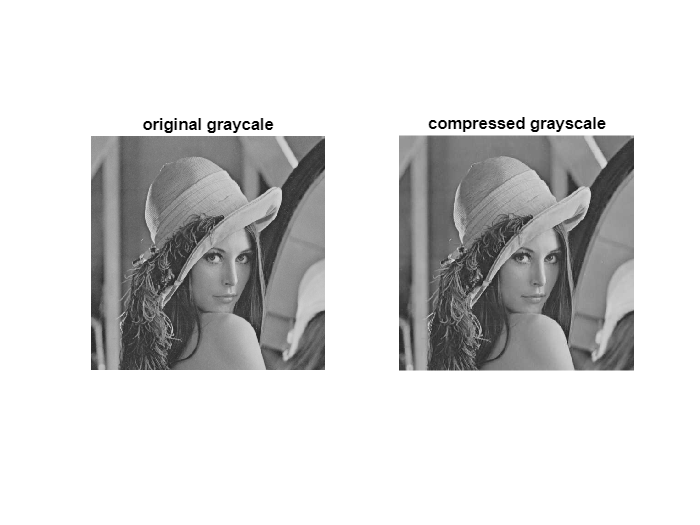

figure;
subplot(1,2,1)
imshow(Y(:,:,1))
title("original graycale")

subplot(1,2,2)
imshow(uint8(iY_d))
title("compressed grayscale")

**Lets see how much pixels doesnt match with the original image. Despite 50% of the pixels arent the same, our eye isnt sensitive to those**

fprintf("Since rounding off and quantization results in lossy compression, lets have a look at the number of mismatched pixels.\n" + ...
    "The number of mismatched pixels is: %d\nPercentage: %.2f", nnz(Y(:,:,1)-uint8(iY_d)), nnz(Y(:,:,1)-uint8(iY_d))*100/(w*h));

Since rounding off and quantization results in lossy compression, lets have a look at the number of mismatched pixels.
The number of mismatched pixels is: 111653
Percentage: 42.59

**All the functions used in this program are listed below**

function y = zigzag(x)
%%%%%% Unrolls a matrix in Zig Zag form %%%%%%

tot_blocks = size(x,1)*size(x,2)/64;    %total number of 8x8 patches in the entire image and single row
tot_blocks_single_dim = size(x,2)/8;
y = zeros(tot_blocks, 64);              %to store the unrolled vector

for i = 1:8:size(x,1)-7
    for j=1:8:size(x,2)-7
        patch = x(i:i+7, j:j+7);
        y(round(i/8)*tot_blocks_single_dim+round(j/8)+1, :) = patch_zigzag(patch);
    end
end
end

function y = patch_zigzag(x)
%%%%%% Unrolls a 8x8 matrix in zig zag form %%%%%%%
%{
Algorithm:
1) Find the diag index of interest(sum - 1) using sum = i+j
2) Find the total number of elements till the previous diag index.
    (i) If prev_diag_index <= centr_diag_index, then k(k+1)/2 formula
    (ii) Else: k(k+1)/2 formula till centr_diag_index, then another formula
3) Computing the offset from (2) will lead us to the index in the zig
    zagged vector.
4) if sum is even, the offset is based on the column index. Else, row index
    (i) if cur_diag_index <= centr_diag_index, we have (1,j) and (i,1) to
        start with
    (ii) ELse: We subtract (cur_diag_index - centr_diag_index) from
        row/col index to start the offet from 1.
%}


y = zeros(1,size(x,1)*size(x,2));
N = 2*size(x,1)-1;
mid_diagonal = (N+1)/2;

for i=1:8
    for j=1:8
        sum = i+j;
        nth_diagonal = sum-1;               % get diagonal
        
        % total prev elements
        if nth_diagonal-1 <= mid_diagonal
            index = (nth_diagonal-1)*(nth_diagonal)/2;
        else
            n_terms_sub = N - (nth_diagonal-1);
            index = mid_diagonal*(mid_diagonal+1)/2 + ((mid_diagonal-1)*mid_diagonal/2 - (n_terms_sub)*(n_terms_sub+1)/2);
        end
        
        % Computing the offset as per the algorithm described above
        if rem(sum,2) == 0
            index = index + j;
            if nth_diagonal > mid_diagonal
                index = index - (nth_diagonal-mid_diagonal);
            end
        else
            index = index + i;
            if nth_diagonal > mid_diagonal
                index = index - (nth_diagonal-mid_diagonal);            % Now offset starts from 1
            end
        end
        y(index) = x(i,j);
    end
end
end


function y = ZRLE(x)
%{
To exploit the sparsity of the unrolled vector, we encode the vector as
(n_zeros b/w last and current non-zero value, current non-zero value)
When we encounter the index after which the vector is completely 0, we
append the symbol "500" indicating the rest are all zeros.

This is not the exact ZRLE used in the algorithm. We stick to this for our
convenience
%}

y = [];
for i = 1:size(x, 1)
    m = x(i,:);
    ind = find(m,1,'last');    %last non zero element
    
    if nnz(x(i,:)) ~= 0
        n_zeros = 0;            %to count number of zeros b/w current and prev non zero values
        for j = 1:ind
            if x(i,j) ~= 0
                %{
                if i ==1 && j<20
                    m(1:20)
                end
                %}
                y = [y,n_zeros,x(i,j)];     %n_zeros and cur_val
                n_zeros = 0;
            else
                n_zeros = n_zeros+1;
            end
        end
    else
        y = [y,0];              % This 8x8 patch has only zeros
    end
    y = [y,500];                % Rest all are 0s
end
end

function [y, dicts, tree] = huff(x)
%{
Usually JPEG uses the Huffman table given in the JPEG standard for both
encoding and decoding. But to illustrate huffman coding, lets use huffman
encoding for each patch.
y       - Encoded sequence
dicts   - Huffman table with symbol, prob, code for each patch
tree    - Huffman tree with all the nodes for each patch

Algorithm:
1) Extract a line(patch) by searching for the symbol 500. 
2) Find the unique elements of the line and compute the probabilities using
    comp_prob() function
3) Build a huffman tree using huffman coding procedure using the function
    huff_encode
%}


y = "";
dicts = {};                             % Since diff patches have diff no of symbols, we use a cell array
tree = [];
i=1;
for k = 1:length(x)
    if x(k) == 500                      % Hunt for each 8x8 patches
        line = x(i:k);
        
        p = comp_prob(line);            % compute the probabilites
        
        [map, t] = huff_encoding(p);    % perform huffman coding algorithm
        
        for j = 1:length(line)
            index = find(p==line(j));
            y = y+map(index);           % encode the sequence
        end
        %{
        if i==1
            line
            p
            y
        end
        %}
        dict = [p,map];
        dicts{end+1} = dict;            % store the code and table
        tree = [tree,t];                % store the tree for decoding
        i = k+1;                        % next line
    end
end
end

function y = comp_prob(x)
u = unique(x);
count = [];
for i = 1:length(u)
    count = [count;nnz(x==u(i))/length(x)];
end
[count_sort, I] = sort(count);                  % sort acc to probabilities
y = [u(I)',count_sort];
end

function [y, tree] = huff_encoding(x)
%{
Function to build the huffman tree.
Each node is a struct variable having the following attributes:
    1) val      - Its current prob value
    2) leftval  - prob of left child
    3) rightval - prob of right child
    4) leftwt   - 0 as per the algorithm
    5) rightwt  - 0 as per the algorithm
    6) symbol(Optional) - For the coarsest level of the tree, it stores the
        symbols corresponding to each probability. This is used to find the
        code easily since symbols are unique but probabilities neednt be.

Algorithm:
    1) Sort the nodes at each iteration wrt their probabilities. Perform
        Huffman coding algorithm.
    2) After building the tree call traversal() function to get the codes
%}


arr_ps = x(:,2);                % probabilites
arr_ps = arr_ps';               
arr_p = [];
for i = 1:length(arr_ps)
    node.symbol = x(i,1);       % symbols at the corasest level
    node.val = arr_ps(i);
    node.leftval = -1;          % No childs
    node.rightval = -1;
    node.leftwt = -1;
    node.rightwt = -1;
    arr_p = [arr_p,node];
end

while length(arr_p) ~= 1        % root node did not occur
    min_1 = arr_p(1).val;
    min_2 = arr_p(2).val;
    
    node.val = min_1+min_2;
    node.leftval = arr_p(1);
    node.rightval = arr_p(2);
    node.leftwt = 0;
    node.rightwt = 1;

    arr_p = [node,arr_p(3:end)];

    % sort the new array of nodes
    arr_val = [];
    for i = 1:length(arr_p)
        arr_val = [arr_val; arr_p(i).val];
    end

    %sort
    [s,I] = sort(arr_val);
    arr_p = arr_p(I);
end

% Generating the code words
y = zeros(size(x(:,2)));
y = traversal(arr_p(1), "", x);
tree = arr_p(1);
end


function y = traversal(node, str, x)  
%{
1) traverse all the way to the left child until node.leftval and rightval
    is none.
2) Compute the code, return one level above and traverse right childs and
    compute the code
%}

y = strings(size(x(:,2)));
if node.leftwt == -1 && node.rightwt == -1              % coarsest level
    ind = find(x(:,1)==node.symbol);
    y(ind) = str;
    return
else                                                    % traverse to the left child
    str1 = str+int2str(node.leftwt);
    y = traversal(node.leftval, str1, x);
    y1 = y;
    str1 = str+int2str(node.rightwt);
    y = traversal(node.rightval, str1, x);              % traverse to the right child
    y = y1+y;
end
end

function dy = decode(y, tree)
%{
Decodes the given encoded sequence.
1) Start from root node and traverse till you reach the coarsest level.
    Decode the sequence using node.symbol or use the table stored in dicts
    cell array
%}

dy = [];
k = 1;
i=1;
while i ~= strlength(y)+1
    node = tree(k);
    while node.leftwt ~= -1 && node.rightwt ~= -1       % traverse to the coarsest depth
        if y(i) == int2str(node.leftwt)
            node = node.leftval;
        else
            node = node.rightval;
        end
        i = i+1;
    end
    dy = [dy,node.symbol];
   
    if node.symbol == 500                               % next 8x8 patch/line
        k = k+1;
    end
end
end

function dy = decodeZRLE(ix)
dy = [];
i = 1;
for j = 1:length(ix)
    if ix(j) == 500
        if j-i == 1
            dy = [dy;zeros(1,64)];                      % this patch is full of zeros
        else
            join = [];
            while i ~= j
                n_zeros = ix(i);
                val = ix(i+1);
                join = [join, zeros(1,n_zeros), val];
                i = i + 2;
            end
            join = [join, zeros(1,64-length(join))];    % append 64 - length(join) zeros
            dy = [dy;join];
        end
        i = j+1;
    end
end
end